# Airfoil: Eppler 197

clear all; close all; clc;

## Flight Conditions Import

Re = 379824;
v = 24; %m/s
gamma = 1.4;
T = 286;
R = 286;

### Design Decisions

sweep_qc = 0; %quarter-chord sweep angle
sweep_max = 0;
d = 0.1; %fuselage diameter [m]
WL = 92.1058; %wing loading
Wg = 22.2297; %gross weight
AR = 4.5; %aspect ratio

## 2D Airfoil Data Import

Cl_alpha = 0.1182;
alpha0 = -2.669; %deg
Cl_min = -0.686;
Cl_max = 1.2295;
Cd_min = 0.0085;
TR = 0.1349;

## Wing Sizing

S = Wg/WL %reference wing area

S = 0.2413

b = sqrt(AR*S) %wing span

b = 1.0421

c = b/AR %chord length

c = 0.2316

## 3D Lift Analysis

####     Mach Number

a = sqrt(gamma*R*T); %local speed of sound
M = v/a

M = 0.0709

####     3D Lift Curve Parameters

CL_max = 0.9*Cl_max*cosd(sweep_qc)

CL_max = 1.1066

beta = sqrt(1 - M^2)

beta = 0.9975

eta = (Cl_alpha*180/pi) / (2*pi/beta)

eta = 1.0751

F = 1.07*(1+d/b)^2

F = 1.2852

Assuming that the reference area is equal to the exposed area, then the wetted area can be estimated. 

S_exp = S;
S_wet = S_exp*(1.977+0.52*TR)

S_wet = 0.4941

Calculating the 3D lift curve slope:

CL_alpha = ((2*pi*AR)/(2+sqrt(4+((AR^2*beta^2)/(eta^2))*(1+((tand(sweep_max)^2)/(beta^2))))))*(S_exp/S)*F;
CL_alpha = CL_alpha*pi/180

CL_alpha = 0.0957

####     Plotting 3D Lift Curve

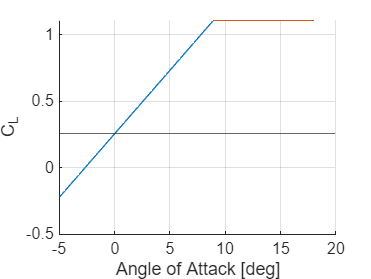

alpha_stall = (CL_max/CL_alpha) + alpha0;
alpha = linspace(-5,alpha_stall,100);
alpha_ps = linspace(alpha_stall,18,100);
CL_PS = CL_max*ones(1,length(alpha_ps));
CL = CL_alpha*(alpha - alpha0);

figure()
hold on
plot(alpha,CL)
plot(alpha_ps,CL_PS)
yline(0.26)
grid on
xlabel('Angle of Attack [deg]')
ylabel('C_L')